# Smart Irrigation System

clc
clear all

## Design Overview

#### Water resevouir

#### PV&BESS system 

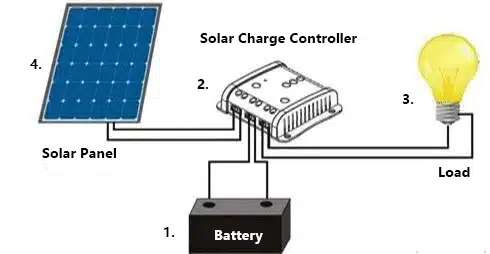

## Energy Simulation

Model load storage and generation to determine ideal component sizing.

#### System Loads Variables

%Set
Load.baselineWattage = 0.65; %wattage while not pumping
Load.pumpWattage = 3.68; %wattage while pumping
Load.psuEffieciency = 0.9; %Battery to load energy effieciency
%Derived
Load.totalWattage = 0 %wattage while pumping

Load = struct with fields:
    baselineWattage: 0.6500
        pumpWattage: 3.6800
     psuEffieciency: 0.9000
       totalWattage: 0


#### PV Generation Variables

%Set
PV.panelWp = 40; %Peak wattage rating of panel
PV.irradiance = 0;
PV.shadingLosses = 0.2; 
PV.sccEffieciency = 0.8; %PV to Battery charging effieciency
%Derived
PV.chargingEnabled = true;
PV.generationWattage = 0

PV = struct with fields:
              panelWp: 40
           irradiance: 0
        shadingLosses: 0.2000
       sccEffieciency: 0.8000
      chargingEnabled: 1
    generationWattage: 0


#### BESS Variables

%Set
Battery1.Chemistry = "LiFePo4";
Battery1.Capacity = 104; %Nominal Wh capacity of the battery
Battery1.DOD = 0.8; %Maximum depth of discharge recommended for battery
Battery1.monthlyStandingEnergyLossPercentage = 0.02; %standing energy losses from battery
Battery1.coulumbicChargeEffieciency = 0.99;
Battery1.coulumbicDichargeEffieciency = 0.99;
Battery1.MaxSOC = 45; %maximum charge SOC limit
Battery1.chargeControlHysteresis = 5;

%Derived
Battery1.SOC = 38;
Battery1.chargeEnergy = 0;
Battery1.dischargeEnergy = 0;
Battery1.cRate = Load.totalWattage/Battery1.Capacity;
Battery1.RTE = Battery1.coulumbicChargeEffieciency * Battery1.coulumbicDichargeEffieciency; %Round trip energy effieciency of the battery
Battery1.selfDischargePower = Battery1.monthlyStandingEnergyLossPercentage/(30.25*24*60);
Battery1.totalPower = 0

Battery1 = struct with fields:
                              Chemistry: "LiFePo4"
                               Capacity: 104
                                    DOD: 0.8000
    monthlyStandingEnergyLossPercentage: 0.0200
             coulumbicChargeEffieciency: 0.9900
           coulumbicDichargeEffieciency: 0.9900
                                 MaxSOC: 45
                chargeControlHysteresis: 5
                                    SOC: 38
                           chargeEnergy: 0
                        dischargeEnergy: 0
                                  cRate: 0
                                    RTE: 0.9801
                     selfDischargePower: 4.5914e-07
                             totalPower: 0


#### Simulation Timetable

%Initialize 24 hour timetable with 1 minute intervals to model system state
%variables
load("SimulationTimetable.mat");
%adjust TT datetime
%TT.Time = TT.Time - seconds(12);

%set
TT.totalPowerIO = zeros(height(TT),1);
TT.pvGeneration = zeros(height(TT),1);

pumpWindow1.begin = 7;
pumpWindow2.begin = 16;
pumpingWindowMinutes = 60;

for i = 1:height(TT)
    %simulate pump load

    if i>= pumpWindow1.begin*60 && i<= pumpWindow1.begin*60 + pumpingWindowMinutes || i>= pumpWindow2.begin*60 && i<= pumpWindow2.begin*60 + pumpingWindowMinutes
        Load.totalWattage = Load.baselineWattage + Load.pumpWattage;
    else
        Load.totalWattage = Load.baselineWattage;
    end

    %Simulate Irradiance as 180deg sin function
    PV.irradiance = -cos(deg2rad(i*(360/1440)));
    if PV.irradiance <= 0 
       PV.irradiance = 0;
    end
    %%REMOVE
    %%PV.irradiance = 0;

    %Disable charging if SOC is >= 45%
    if Battery1.SOC >= (45 + (Battery1.chargeControlHysteresis/2))
        PV.chargingEnabled = false;
    elseif Battery1.SOC <= (45 - (Battery1.chargeControlHysteresis/2))
        PV.chargingEnabled = true;
    else 
        PV.chargingEnabled = false;
    end
    
    %PV generation
    PV.generationWattage = PV.chargingEnabled * PV.irradiance * PV.panelWp * PV.sccEffieciency * (1-PV.shadingLosses);
    
    %Battery charge energy from PV generation (in Wh)
    Battery1.chargeEnergy = (PV.generationWattage * Battery1.coulumbicChargeEffieciency)/60;
    %Battery discharge energy from loads and self discharge (in Wh)
    Battery1.dischargeEnergy = ((Load.totalWattage/(Load.psuEffieciency*Battery1.coulumbicDichargeEffieciency)) + Battery1.selfDischargePower)/60;
    %Total wattage input and output of the battery
    Battery1.totalPower = (Battery1.chargeEnergy - Battery1.dischargeEnergy) * 60;
    %Battery SOC change with PV generation and load (in watts) 
    Battery1.SOC = Battery1.SOC + (((Battery1.chargeEnergy - Battery1.dischargeEnergy)/Battery1.Capacity)*100);
    
    %Define TT variables
    TT.Irradiance(i) = PV.irradiance;
    TT.pvGenerationWattage(i) = PV.generationWattage;
    TT.totalPowerIO(i) = Battery1.totalPower;
    TT.Load(i) = Load.totalWattage;
    TT.SOC(i) = Battery1.SOC;
end


%TR = timerange("2008-06-20","2008-09-22")
clear("i","T")

%tableResolution = minutes(TT.Time(2)-TT.Time(1)); 

### Graph Inputs and Output

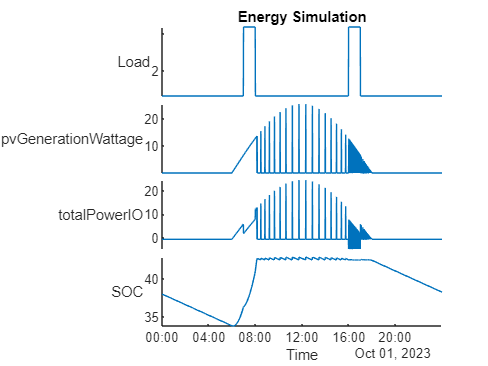

figure
%s1 = stackedplot(TT,["Load","Irradiance","Charge Current","SOC"]);
s1 = stackedplot(TT,["Load","pvGenerationWattage","totalPowerIO","SOC"]);
title("Energy Simulation")

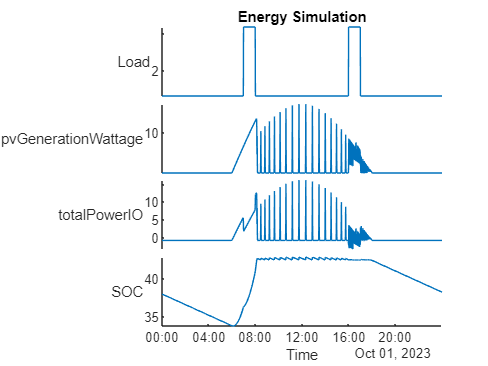


% figure
% %s1 = stackedplot(TT,["Load","Irradiance","Charge Current","SOC"]);
% s2 = stackedplot(TTsmoothed,["Load","pvGenerationWattage","totalPowerIO","SOC"]);
% title("Energy Simulation")

#### Extended simulation with PV prediction and SOC control

clc
clear all

#### System Loads Variables

%Set
Load.baselineWattage = 0.65; %wattage while not pumping
Load.pumpWattage = 3.68; %wattage while pumping
Load.psuEffieciency = 0.9; %Battery to load energy effieciency
%Derived
Load.totalWattage = 0 %wattage while pumping

Load = struct with fields:
    baselineWattage: 0.6500
        pumpWattage: 3.6800
     psuEffieciency: 0.9000
       totalWattage: 0


#### PV Generation Variables

%Set
PV.panelWp = 40; %Peak wattage rating of panel
PV.irradiance = 0;
PV.shadingLosses = 0.2; 
PV.sccEffieciency = 0.8; %PV to Battery charging effieciency
%Derived
PV.chargingEnabled = true;
PV.generationWattage = 0

PV = struct with fields:
              panelWp: 40
           irradiance: 0
        shadingLosses: 0.2000
       sccEffieciency: 0.8000
      chargingEnabled: 1
    generationWattage: 0


#### BESS Variables

%Set
Battery1.Chemistry = "LiFePo4";
Battery1.Capacity = 61.44; %Nominal Wh capacity of the battery
Battery1.DOD = 0.8; %Maximum depth of discharge recommended for battery
Battery1.monthlyStandingEnergyLossPercentage = 0.02; %standing energy losses from battery
Battery1.coulumbicChargeEffieciency = 0.99;
Battery1.coulumbicDichargeEffieciency = 0.99;
Battery1.MaxSOC = 45; %maximum charge SOC limit
Battery1.chargeControlHysteresis = 2;

%Derived
Battery1.SOC = 38;
Battery1.chargeEnergy = 0;
Battery1.dischargeEnergy = 0;
Battery1.cRate = Load.totalWattage/Battery1.Capacity;
Battery1.RTE = Battery1.coulumbicChargeEffieciency * Battery1.coulumbicDichargeEffieciency; %Round trip energy effieciency of the battery
Battery1.selfDischargePower = Battery1.monthlyStandingEnergyLossPercentage/(30.25*24*60);
Battery1.totalPower = 0

Battery1 = struct with fields:
                              Chemistry: "LiFePo4"
                               Capacity: 61.4400
                                    DOD: 0.8000
    monthlyStandingEnergyLossPercentage: 0.0200
             coulumbicChargeEffieciency: 0.9900
           coulumbicDichargeEffieciency: 0.9900
                                 MaxSOC: 45
                chargeControlHysteresis: 2
                                    SOC: 38
                           chargeEnergy: 0
                        dischargeEnergy: 0
                                  cRate: 0
                                    RTE: 0.9801
                     selfDischargePower: 4.5914e-07
                             totalPower: 0


%Initialize 24 hour timetable with 1 minute intervals to model system state
%variables
load("SimulationTimetable4.mat");

S = timerange('01/02/2007 00:00:00','12/31/2007 23:59:00')

S = 	timetable timerange subscript:

		Select timetable rows with times in the half-open interval:
		[02-Jan-2007 00:00:00, 31-Dec-2007 23:59:00)

	See Select Times in Timetable.


TT2 = TT2(S,:)

TT2 = 524159×2 timetable
          datetime          air_temp    gti
    ____________________    ________    ___

    02-Jan-2007 00:00:00       12        0 
    02-Jan-2007 00:01:00       12        0 
    02-Jan-2007 00:02:00       12        0 
    02-Jan-2007 00:03:00       12        0 
    02-Jan-2007 00:04:00       12        0 
    02-Jan-2007 00:05:00       12        0 
    02-Jan-2007 00:06:00       12        0 
    02-Jan-2007 00:07:00       12        0 
    02-Jan-2007 00:08:00       12        0 
    02-Jan-2007 00:09:00       12        0 
    02-Jan-2007 00:10:00       12        0 
    02-Jan-2007 00:11:00       12        0 
    02-Jan-2007 00:12:00       12  

%VAriables for SOC control
Load.dailyConsumption = 0.03032;

%set
TT2.totalPowerIO = zeros(height(TT2),1);
TT2.pvGeneration = zeros(height(TT2),1);

pumpWindow1.begin = 6;
pumpWindow2.begin = 14;
pumpingWindowMinutes = 120;

minutesInADay = 24*60;

%for i = 1: 99 * minutesInADay
for i = 1:height(TT2)
    %simulate pump load
    j = mod(i,minutesInADay);
    if j >= pumpWindow1.begin*60 && j<= pumpWindow1.begin*60 + pumpingWindowMinutes || j>= pumpWindow2.begin*60 && j<= pumpWindow2.begin*60 + pumpingWindowMinutes
        Load.totalWattage = Load.baselineWattage + Load.pumpWattage;
    else
        Load.totalWattage = Load.baselineWattage;
    end

    %Simulate Irradiance as 180deg sin function
    PV.irradiance = (TT2.gti(i)/1000);
    if PV.irradiance <= 0 
       PV.irradiance = 0;
    end
    %%REMOVE
    %%PV.irradiance = 0;

    %Disable charging if SOC is >= 45%
    if Battery1.SOC >= (45 + (Battery1.chargeControlHysteresis/2))
        PV.chargingEnabled = false;
    end
    if Battery1.SOC <= (45 - (Battery1.chargeControlHysteresis/2))
        PV.chargingEnabled = true;
    end
    
    %PV generation
    if PV.chargingEnabled == true
    PV.generationWattage = PV.irradiance * PV.panelWp * PV.sccEffieciency * (1-PV.shadingLosses);
    end
    if PV.chargingEnabled == false
    PV.generationWattageAvailable = PV.irradiance * PV.panelWp * PV.sccEffieciency * (1-PV.shadingLosses);
        if PV.generationWattageAvailable >= (Load.totalWattage/(Load.psuEffieciency*Battery1.coulumbicDichargeEffieciency))
        PV.generationWattage = Load.totalWattage/(Load.psuEffieciency*Battery1.coulumbicDichargeEffieciency);
        else
        PV.generationWattage = PV.generationWattageAvailable;
        end
    end

    %Battery charge energy from PV generation (in Wh)
    Battery1.chargeEnergy = (PV.generationWattage * Battery1.coulumbicChargeEffieciency)/60;
    %Battery discharge energy from loads and self discharge (in Wh)
    Battery1.dischargeEnergy = ((Load.totalWattage/(Load.psuEffieciency*Battery1.coulumbicDichargeEffieciency)) + Battery1.selfDischargePower)/60;
    %Total wattage input and output of the battery
    Battery1.totalPower = (Battery1.chargeEnergy - Battery1.dischargeEnergy) * 60;
    %Battery SOC change with PV generation and load (in watts) 
    Battery1.SOC = Battery1.SOC + (((Battery1.chargeEnergy - Battery1.dischargeEnergy)/Battery1.Capacity)*100);
    %Battery1.SOC = Battery1.SOC + ((PV.generationWattage - (Load.totalWattage/(Load.psuEffieciency*Battery1.coulumbicDichargeEffieciency))/Battery1.Capacity)*100);
    
    %Define TT variables
    TT2.Irradiance(i) = PV.irradiance;
    TT2.pvGenerationWattage(i) = PV.generationWattage;
    TT2.totalPowerIO(i) = Battery1.totalPower;
    TT2.Load(i) = Load.totalWattage;
    TT2.SOC(i) = Battery1.SOC;
end


%TR = timerange("2008-06-20","2008-09-22")
clear("i","T")

%tableResolution = minutes(TT2.Time(2)-TT2.Time(1)); 

### Graph Inputs and Output

% S = timerange('03/01/2007 00:00:00','03/02/2007 23:59:00')
% TT2copy = TT2(S,:)
TT2copy = TT2;

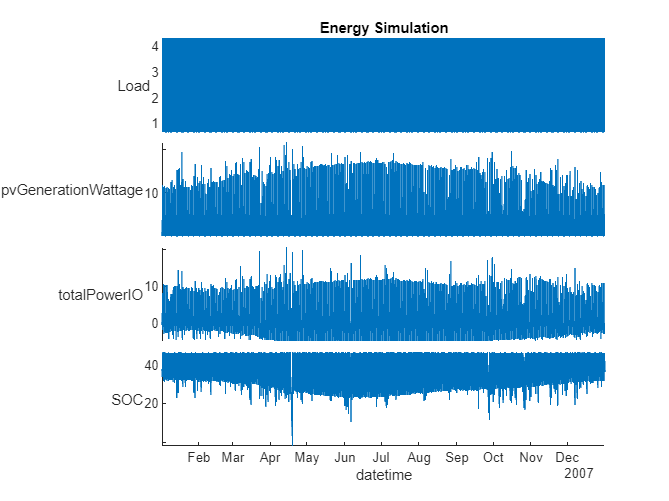

figure
%s1 = stackedplot(TT2,["Load","Irradiance","Charge Current","SOC"]);
s1 = stackedplot(TT2copy ,["Load","pvGenerationWattage","totalPowerIO","SOC"]);
title("Energy Simulation")


%figure
%s1 = stackedplot(TT2,["Load","Irradiance","Charge Current","SOC"]);
%s2 = stackedplot(TT2smoothed,["Load","pvGenerationWattage","totalPowerIO","SOC"]);
%title("Energy Simulation")

S = timerange('04/10/2007 00:00:00','04/10/2007 23:59:00')

S = 	timetable timerange subscript:

		Select timetable rows with times in the half-open interval:
		[10-Apr-2007 00:00:00, 10-Apr-2007 23:59:00)

	See Select Times in Timetable.


TT2copy1 = TT2(S,:)

TT2copy1 = 1439×8 timetable
          datetime          air_temp    gti    totalPowerIO    pvGeneration    Irradiance    pvGenerationWattage    Load     SOC  
    ____________________    ________    ___    ____________    ____________    __________    ___________________    ____    ______

    10-Apr-2007 00:00:00       11        0       -0.72952           0              0                  0             0.65    29.266
    10-Apr-2007 00:01:00       11        0       -0.72952           0              0                  0             0.65    29.246
    10-Apr-2007 00:02:00       11        0       -0.72952           0              0      

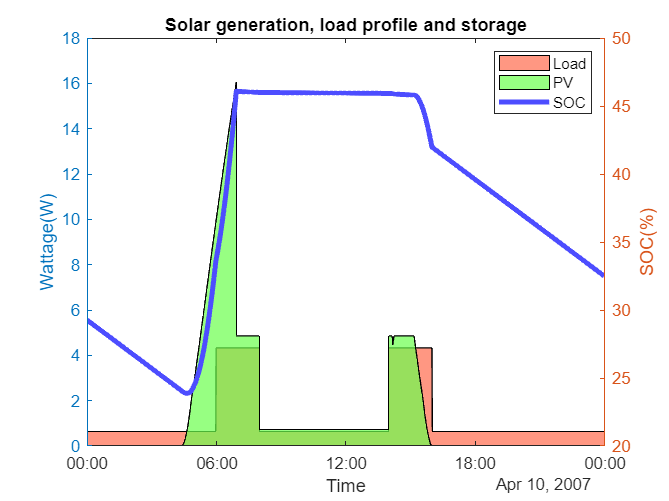

figure
yyaxis left
s2 = area(TT2copy1.datetime,TT2copy1.Load);
s2.FaceAlpha = 0.7;
s2.FaceColor = [1.00 0.42 0.30];
hold on
s3 = area(TT2copy1.datetime,TT2copy1.pvGenerationWattage);
s3.FaceAlpha = 0.7;
s3.FaceColor = [0.42 1.00 0.30];
xlabel('Time')
ylabel('Wattage(W)')
yyaxis right
s4 = plot(TT2copy1.datetime,TT2copy1.SOC);
s4.LineWidth = 3;
s4.Color = [0.30 0.30 1.00];
title('Solar generation, load profile and storage')
ylabel('SOC(%)')
legend('Load','PV','SOC')
hold off

Compute daily DOD

% Retime timetable
maxSOC = retime(TT2copy,"regular","max","TimeStep",caldays(1))

maxSOC = 364×8 timetable
     datetime      air_temp    gti     totalPowerIO    pvGeneration    Irradiance    pvGenerationWattage    Load     SOC  
    ___________    ________    ____    ____________    ____________    __________    ___________________    ____    ______

    02-Jan-2007       24       1072       8.0649            0            1.072             11.674           4.33    46.178
    03-Jan-2007       26       1069       10.381            0            1.069             11.223           4.33    46.228
    04-Jan-2007       29       1072       10.412            0            1.072             11.469           4.33    46.166
  

% Retime timetable
minSOC = retime(TT2copy,"regular","min","TimeStep",caldays(1))

minSOC = 364×8 timetable
     datetime      air_temp    gti    totalPowerIO    pvGeneration    Irradiance    pvGenerationWattage    Load     SOC  
    ___________    ________    ___    ____________    ____________    __________    ___________________    ____    ______

    02-Jan-2007       11        0       -1.9299            0              0                  0             0.65    33.737
    03-Jan-2007       13        0       -2.8575            0              0                  0             0.65     31.91
    04-Jan-2007       15        0        -2.523            0              0                  0             0.65     31.42
    

maxSOC.DOD = zeros(height(maxSOC),1);
for i = 1:height(minSOC)
    maxSOC.DOD(i) = maxSOC.SOC(i) - minSOC.SOC(i);
end

figure
h1 = histogram(maxSOC.DOD,'Normalization','probability')

h1 =   Histogram with properties:

             Data: [364×1 double]
           Values: [0.0137 0.1648 0.1209 0.1676 0.2225 0.1868 0.0659 0.0302 0.0165 0.0027 0 0.0055 0 0 0 0 0 0 0.0027]
          NumBins: 19
         BinEdges: [12 14 16 18 20 22 24 26 28 30 32 34 36 38 40 42 44 46 48 50]
         BinWidth: 2
        BinLimits: [12 50]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


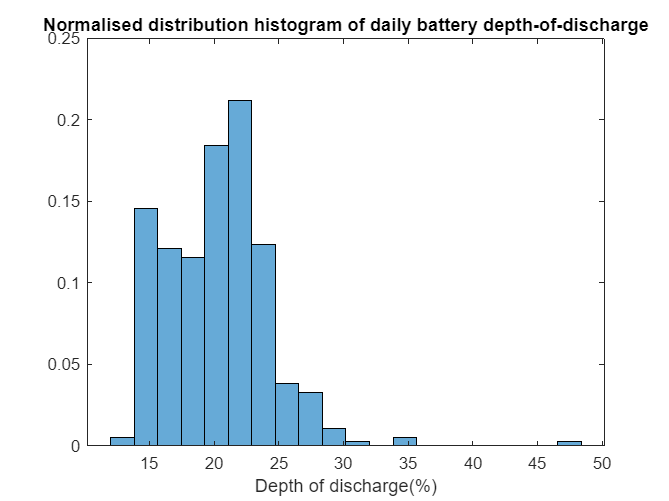

h1.NumBins = 20;
title('Normalised distribution histogram of daily battery depth-of-discharge')
xlabel('Depth of discharge(%)')

%ylabel('Contribution(%)')
% hold on
% y = 10:1:25;
% mu = 15;
% sigma = 2;
% f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
% plot(y,f,'LineWidth',1.5)